clc % clear command window
clear all % clear workspace

1. Set up modeling options, load dataset, and train model. For detailed explanations of these steps, please see the tutorials in the /tutorials/multivariate_regression or /tutorials/multivariate_classification folders. For this example, we just train a model on the full training dataset with hyper-parameter optimization. We will then apply the trained model to an independent test dataset. 

% Add paths to relevant functions
cfg_train.model_dir = '/Shared/boeslab/Users/jcgriffis/mlsm_code_repo/model_code'; % path to toolkit
addpath(genpath(fullfile(cfg_train.model_dir, 'common'))); % add common folder to path

% Specify output directory (Note - output folders for specific analyses will be created in this directory)
out_dir = '/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/tutorial_results';

% Specify data modality and supply brain mask
cfg_train.modality = 'lesion'; % predictor modality - 'lesion' or 'other' 
cfg_train.mask_path = fullfile('/Shared/boeslab/Data/Lesion/Iowa/Registry/derivedData/LesionQuantificationToolkit/Chronic/Yeo7200/Lesion_3mm/mask/brain_mask.nii'); % path to brain mask

% Specify general modeling options
cfg_train.model_spec = 'ridge'; % model to fit
cfg_train.fit_explanatory_model = 1; % fit explanatory model to full dataset 
cfg_train.optimize_hyperparams = 1; % use cross-validation to optimize model hyperparameters
cfg_train.cross_validation = 0; % don't use cross-validation to estimate out-of-sample predictive performance
cfg_train.bootstrap = 0; % don't use bootstrap resampling for significance testing of coefficients
cfg_train.permutation = 0; % don't use permutation testing for significance testing of model fit (and/or coefficients)

% Initialize cfg_train file with default settings given general modeling options
cfg_train = get_default_model_cfg(cfg_train); 

cfg.jackknife field is empty; setting to 0 with default settings
Analysis type is lesion - setting defaults
MATLAB parallel processing functionality detected; parallel processing enabled


% Specify path to CSV containing study IDs and behavioral scores
train_csv = readtable('/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/behavior/train_csv.csv'); % read in CSV file as table
id_col = 'study_id'; % name of column containing 4-digit IDs
beh_col = 'mae_token'; % name of column containing behavior of interest

% Specify lesion directory and indicate whether patients are registry patients
lesion_dir = '/Shared/boeslab/Data/Lesion/Iowa/Registry/derivedData/LesionQuantificationToolkit/Chronic/Yeo7200/Lesion_3mm'; % directory containing lesion images
registry_flag = 1; % CSV contains numeric registry IDs (i.e., '0's need to be appended for subjects < 1000)

% Get formatted lesion matrix, behavioral data, subject IDs, and mask volume/header and in-mask indices
% Note: outputs are stored as fields in cfg_train structure 
cfg_train = get_and_format_lesion_data(train_csv, id_col, beh_col, registry_flag, lesion_dir, cfg_train);

All subjects with behavioral data have lesion files, N=141 patients will be included


% Customize analysis parameters

% Lesion-mapping
cfg_train.freq_thresh = 10; % only include voxels that are lesioned in at least 10 patients
cfg_train.dtlvc = 1; % Use direct total lesion volume control (Zhang et al., 2014)

% Variable standardization
cfg_train.standardize = 0; % Standardize (1 - standardize X, 2 - standardize Y, 3 - standardize X & Y)

% Hyper-parameter optimization
cfg_train.hp_opt.cv_type = 'KFold'; % Do K-fold cross-validation for hyper-parameter optimization
cfg_train.hp_opt.folds = 5; % 5-fold cross-validation
cfg_train.hp_opt.repeats = 5; % 5 repeats of 5-fold cross-validation

% Stratification for cross-validation 
cfg_train.strat_var = []; % stratification variable if desired

% Specify output directory
cfg_train.out_dir = fullfile(out_dir, [cfg_train.model_spec '_' beh_col '_independent_pred']);

% fit model with CV hyperparameter optimization and selected significance testing
[model_results] = fit_and_evaluate_model(cfg_train);

Trimming data to retain columns with at least 10 observations greater than or equal to 1
14 subjects have no predictor data after trimming...removing from analysis
Applying direct total lesion volume control...
Running 5 repeats of 5-fold optimization for model hyperparameters
Hyper-parameter optimization iteration:1/5
Hyper-parameter optimization iteration:2/5
Hyper-parameter optimization iteration:3/5
Hyper-parameter optimization iteration:4/5
Hyper-parameter optimization iteration:5/5
Optimal lambda = 0.00055395, fitting model with optimal lambda
Finished running modeling analysis
Time to to complete:0.32333 minutes


2. Now that we've trained the model, we load in the data for the test set. We store it in a new cfg struct named "cfg_test". We also copy in the brain mask indices from the cfg_train struct to allow for extracting the in-brain voxels from the test set lesion images. Note that this assumes that the lesion images for the training and test datasets are registered to the same template and have the same image and voxel dimensions. The new "cfg_test" struct contains the behavioral data and lesion data for the test dataset.  

% Load test dataset behavior and lesion data

% Specify path to CSV containing study IDs and behavioral scores
test_csv = readtable('/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/behavior/test_csv.csv'); % read in CSV file as table
id_col = 'study_id'; % name of column containing 4-digit IDs
beh_col = 'mae_token'; % name of column containing behavior of interest

% Specify lesion directory and indicate whether patients are registry patients
lesion_dir = '/Shared/boeslab/Data/Lesion/Iowa/Registry/derivedData/LesionQuantificationToolkit/Chronic/Yeo7200/Lesion_3mm'; % directory containing lesion images
registry_flag = 1; % CSV contains numeric registry IDs (i.e., '0's need to be appended for subjects < 1000)

% Get formatted lesion matrix, behavioral data, subject IDs, and mask volume/header and in-mask indices
cfg_test = struct(); % Create new cfg_train struct to store data for test set
cfg_test.mask_inds = cfg_train.mask_inds; % Assign same brain mask as training set
cfg_test = get_and_format_lesion_data(test_csv, id_col, beh_col, registry_flag, lesion_dir, cfg_test);

All subjects with behavioral data have lesion files, N=141 patients will be included


3. Next, we provide the model_results struct and the X subfield of cfg_test (this is the lesion matrix for the test set) to the function predict_new(). This produces predicted scores for the test dataset. We can then evaluate the prediction performance for the test set using the correlation between predicted and observed scores, by calculating the MSE, and by calculating the R-squared. 

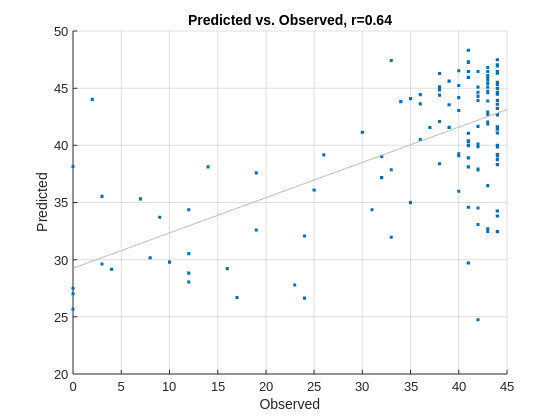

%% Get predictions for test set using trained model
pred_y = predict_new(model_results, cfg_test.X); 

% Compute MSE and R-squared 
r2_test= get_model_r2(cfg_test.Y, pred_y);
mse_test = get_mse(cfg_test.Y, pred_y);

% Plot predicted vs. observed scores for test dataset
scatter(cfg_test.Y, pred_y, 50, '.'); grid on;
lsline; xlabel('Observed'); ylabel('Predicted');
title(['Predicted vs. Observed, r=' num2str(round(corr(cfg_test.Y, pred_y),2))]);

% Print MSE and R-squared
disp(['R-squared:' num2str(round(r2_test,2))]);

R-squared:0.25


disp(['MSE:' num2str(round(mse_test,2))]);

MSE:115.77
